**Load the input image**

img = imread('Fig0445(a)(characters_test_pattern).tif'); 
[M, N] = size(img);

**Define cutoff frequencies & order**

D0_values = [10, 30, 60, 160, 460];
n = 2;

**Create frequency coordinates**

[U, V] = meshgrid(-N/2:N/2-1, -M/2:M/2-1);
D = sqrt(U.^2 + V.^2);

**Apply Butterworth Low Pass Filter and display the original image and results**

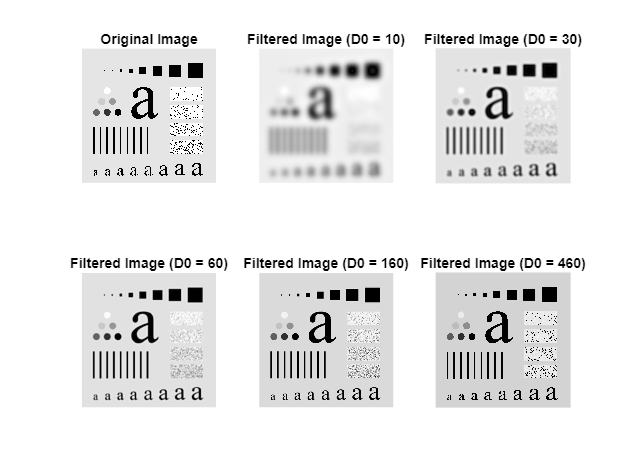

figure;

subplot(2, 3, 1);
imshow(img, []); 
title('Original Image');

for i = 1:length(D0_values)
    D0 = D0_values(i);
    
    H = 1 ./ (1 + (D / D0).^(2 * n));
    
    img_fft = fftshift(fft2(img));
    img_fft_filtered = H .* img_fft;
    img_filtered = abs(ifft2(ifftshift(img_fft_filtered)));
    
    subplot(2, 3, i+1);
    imshow(img_filtered, []); 
    title(['Filtered Image (D0 = ', num2str(D0), ')']);
end